%% ========================================================================
%%  MASTER SCRIPT: BENCHMARK COMPLETO (COMMERCIAL VS CUSTOM)
%% ========================================================================
clear; clc; close all;

% --- 0. CONFIGURAZIONE UTENTE ---
% Percorsi File Input
filename_commercial = './Data/MG996R_data.xlsx'; 

% File Custom Statici (Rampa)
file1_ramp = 'servo_benchmark_FW.mat';
file2_ramp = 'servo_benchmark_BW.mat';

% File Custom Dinamici (Step) - Base nome
% Atteso: 'servo_benchmark_step1.mat', 'step15.mat', 'step90.mat'
file_step_base = 'servo_benchmark_step'; 

% Configurazione Salvataggio
save_figures = true; 
save_path = '../TESI/images/';
if save_figures && ~exist(save_path, 'dir'); mkdir(save_path); end

% --- CONFIGURAZIONE STILE GRAFICO ---
font_size = 20;       % DIMENSIONE FONT MASTER
line_width = 2; 

% Colori Curve
col_fw = [0 0.4470 0.7410];      % Blu (Forward)
col_bw = [0.8500 0.3250 0.0980]; % Arancione (Backward)
col_ideal = [0 0 0];             % Nero (Ideal Line)

% Colori Step Response
col_ref_step  = [0.3010 0.7450 0.9330]; % Azzurro Ciano
col_meas_step = [0.6350 0.0780 0.1840]; % Rosso Mattone

% Colori Istogramma Confronto
col_motorA = [0.4 0.4 0.4];      % Grigio Scuro (Comm. A)
col_motorB = [0.7 0.7 0.7];      % Grigio Chiaro (Comm. B)
col_new    = [0.4660 0.6740 0.1880]; % Verde (Custom)


%% ========================================================================
%% PARTE 1: ANALISI STATICA COMMERCIALI (MG996R)
%% ========================================================================
fprintf('--- 1. ELABORAZIONE MG996R (COMMERCIALE) ---\n');

--- 1. ELABORAZIONE MG996R (COMMERCIALE) ---


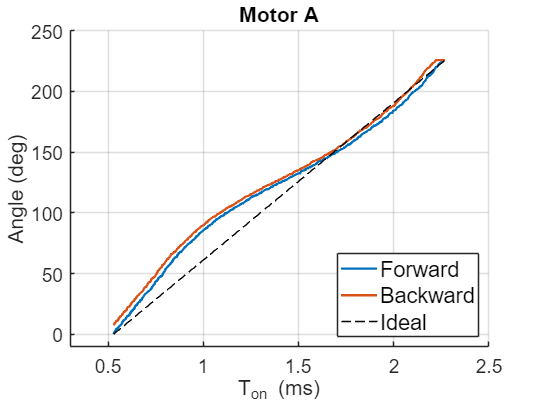


data_table = readtable(filename_commercial); 

% --- 1.1 Motore A ---
TA = data_table.APW; FA = data_table.AFW; BA = data_table.ABW;
vA = ~isnan(TA) & ~isnan(FA) & ~isnan(BA);
TA = TA(vA); FA = FA(vA); BA = BA(vA);

% Metriche A
mA = (max([max(FA),max(BA)]) - min([min(FA),min(BA)])) / (max(TA)-min(TA));
qA = min([min(FA),min(BA)]) - (mA*min(TA));
Y_id_A = mA*TA + qA;

Err_FA = FA - Y_id_A; Err_BA = BA - Y_id_A;
RMSE_FW_A = sqrt(mean(Err_FA.^2));
RMSE_BW_A = sqrt(mean(Err_BA.^2));
RMSE_Glob_A = sqrt(mean([Err_FA; Err_BA].^2));
MaxErr_A = max(abs([Err_FA; Err_BA]));

% Hysteresis Normalizzata (deg)
RawArea_A = abs(trapz(TA, FA - BA));
Hyst_Avg_A = RawArea_A / (max(TA) - min(TA));

% --- 1.2 Motore B ---
TB = data_table.BPW; FB = data_table.BFW; BB = data_table.BBW;
vB = ~isnan(TB) & ~isnan(FB) & ~isnan(BB);
TB = TB(vB); FB = FB(vB); BB = BB(vB);

% Metriche B
mB = (max([max(FB),max(BB)]) - min([min(FB),min(BB)])) / (max(TB)-min(TB));
qB = min([min(FB),min(BB)]) - (mB*min(TB));
Y_id_B = mB*TB + qB;

Err_FB = FB - Y_id_B; Err_BB = BB - Y_id_B;
RMSE_FW_B = sqrt(mean(Err_FB.^2));
RMSE_BW_B = sqrt(mean(Err_BB.^2));
RMSE_Glob_B = sqrt(mean([Err_FB; Err_BB].^2));
MaxErr_B = max(abs([Err_FB; Err_BB]));

% Hysteresis Normalizzata (deg)
RawArea_B = abs(trapz(TB, FB - BB));
Hyst_Avg_B = RawArea_B / (max(TB) - min(TB));

% --- 1.3 Plot Commerciali ---

% --- PARAMETRI LIMITI ASSI ---
x_limits = [0.3 2.5];   % Limiti asse X (T_on)
y_limits = [-10 250]; % Limiti asse Y (Angle)
% -----------------------------

f1 = figure('Name','Comm A','Color','w','Position',[50,50,600,450]); hold on; grid on;
plot(TA, FA, '-', 'Color',col_fw, 'LineWidth',line_width); 
plot(TA, BA, '-', 'Color',col_bw, 'LineWidth',line_width);
plot([min(TA) max(TA)], [min(Y_id_A) max(Y_id_A)], '--', 'Color',col_ideal);

xlabel('T_{on} (ms)', 'FontSize', font_size); 
ylabel('Angle (deg)', 'FontSize', font_size); 
title('Motor A', 'FontSize', font_size+2);

% Impostazione limiti e legenda
xlim(x_limits);
ylim(y_limits);
legend('Forward', 'Backward', 'Ideal', 'Location', 'southeast', 'FontSize', font_size-2);

ax = gca; ax.FontSize = font_size - 4; % Ticks

if save_figures; exportgraphics(f1, fullfile(save_path,'motor_char_A.pdf'), 'ContentType', 'vector'); end

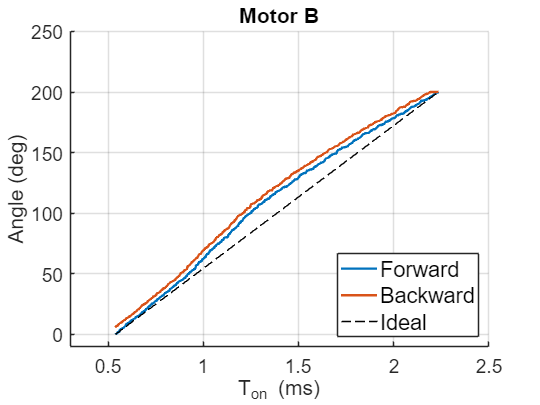


f2 = figure('Name','Comm B','Color','w','Position',[100,100,600,450]); hold on; grid on;
plot(TB, FB, '-', 'Color',col_fw, 'LineWidth',line_width); 
plot(TB, BB, '-', 'Color',col_bw, 'LineWidth',line_width);
plot([min(TB) max(TB)], [min(Y_id_B) max(Y_id_B)], '--', 'Color',col_ideal);

xlabel('T_{on} (ms)', 'FontSize', font_size); 
ylabel('Angle (deg)', 'FontSize', font_size); 
title('Motor B', 'FontSize', font_size+2);

% Impostazione limiti e legenda
xlim(x_limits);
ylim(y_limits);
legend('Forward', 'Backward', 'Ideal', 'Location', 'southeast', 'FontSize', font_size-2);

ax = gca; ax.FontSize = font_size - 4;

if save_figures; exportgraphics(f2, fullfile(save_path,'motor_char_B.pdf'), 'ContentType', 'vector'); end



%% ========================================================================
%% PARTE 2: ANALISI STATICA CUSTOM (LINEARITÀ)
%% ========================================================================
fprintf('--- 2. ELABORAZIONE CUSTOM STATICA ---\n');

--- 2. ELABORAZIONE CUSTOM STATICA ---


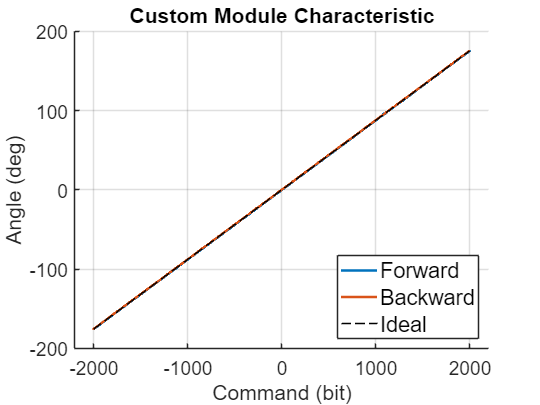

sig_norm = 'q3_hil'; sig_exp = 'cmd'; K = 180/2048; 

% --- 2.1 Forward ---
d1 = load(file1_ramp);
rf1 = d1.out.logsout.getElement(sig_norm).Values.Data(:)*K;
rs1 = d1.out.logsout.getElement(sig_exp).Values.Data(:);
X1 = repelem(rs1(1:end-1), 10); Y1 = rf1(1:length(X1));
% Trim e Glitch Fix
X1 = X1(2:end-1); Y1 = Y1(2:end-1);
if length(Y1) >= 30975; Y1(30796) = Y1(30975); end 

% --- 2.2 Backward ---
d2 = load(file2_ramp);
rf2 = d2.out.logsout.getElement(sig_norm).Values.Data(:)*K;
rs2 = d2.out.logsout.getElement(sig_exp).Values.Data(:);
X2 = repelem(rs2(1:end-1), 10); Y2 = rf2(1:length(X2));
X2 = X2(2:end-1); Y2 = Y2(2:end-1);

% --- 2.3 Metriche Statiche Custom ---
Y_id_1 = X1*K; Y_id_2 = X2*K;
Err_1 = Y1 - Y_id_1; Err_2 = Y2 - Y_id_2;

RMSE_FW_New = sqrt(mean(Err_1.^2));
RMSE_BW_New = sqrt(mean(Err_2.^2));
RMSE_Glob_New = sqrt(mean([Err_1; Err_2].^2));
MaxErr_New = max(abs([Err_1; Err_2]));

if length(Y1) == length(Y2)
    RawArea_New = abs(trapz(X1, Y1 - Y2));
else
    RawArea_New = abs(trapz(X1, Y1) - trapz(X2, Y2));
end
Hyst_Avg_New = RawArea_New / (max(X1) - min(X1));

% --- 2.4 Plot Custom Full ---
f3 = figure('Name','Custom Full','Color','w','Position',[150,150,600,450]); hold on; grid on;
plot(X1, Y1, 'Color',col_fw, 'LineWidth',line_width); plot(X2, Y2, 'Color',col_bw, 'LineWidth',line_width);
plot([-2000 2000], [-2000*K 2000*K], '--', 'Color',col_ideal);
xlim([-2200 2200]); ylim([-200 200]); 

xlabel('Command (bit)', 'FontSize', font_size); 
ylabel('Angle (deg)', 'FontSize', font_size); 
title('Custom Module Characteristic', 'FontSize', font_size+2);
legend('Forward', 'Backward', 'Ideal', 'Location', 'southeast', 'FontSize', font_size-2);
ax = gca; ax.FontSize = font_size - 4;

if save_figures; exportgraphics(f3, fullfile(save_path,'custom_linearity.pdf'), 'ContentType', 'vector'); end

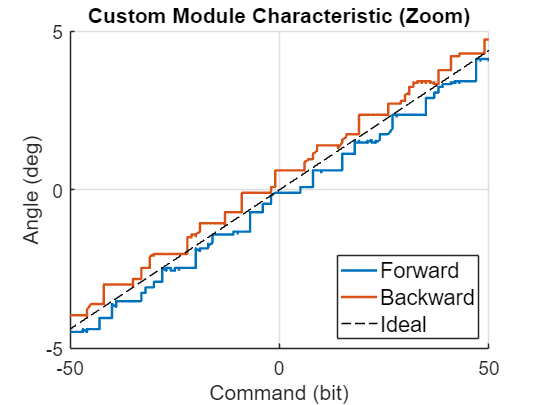


% --- 2.5 Plot Custom Zoom ---
f4 = figure('Name','Custom Zoom','Color','w','Position',[200,200,600,450]); hold on; grid on;
plot(X1, Y1, 'Color',col_fw, 'LineWidth',line_width); plot(X2, Y2, 'Color',col_bw, 'LineWidth',line_width);
plot([-2000 2000], [-2000*K 2000*K], '--', 'Color',col_ideal);
xlim([-50 50]); ylim([-5 5]); 

xlabel('Command (bit)', 'FontSize', font_size); 
ylabel('Angle (deg)', 'FontSize', font_size); 
title('Custom Module Characteristic (Zoom)', 'FontSize', font_size+2);
legend('Forward', 'Backward', 'Ideal', 'Location', 'southeast', 'FontSize', font_size-2);
ax = gca; ax.FontSize = font_size - 4;

if save_figures; exportgraphics(f4, fullfile(save_path,'custom_linearity_zoom.pdf'), 'ContentType', 'vector'); end

%% ========================================================================
%% PARTE 3: ANALISI DINAMICA CUSTOM (STEP RESPONSE)
%% ========================================================================
fprintf('--- 3. ELABORAZIONE CUSTOM DINAMICA ---\n');

--- 3. ELABORAZIONE CUSTOM DINAMICA ---


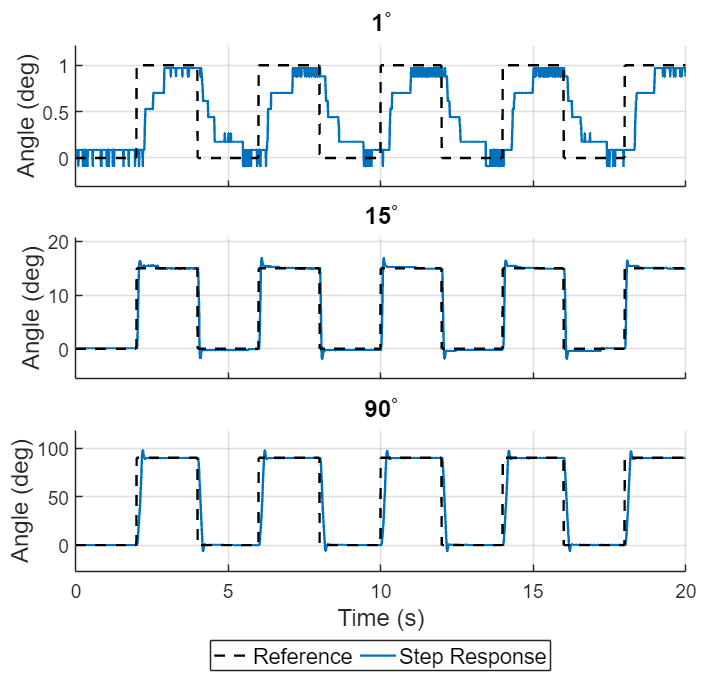


step_vals = [1, 15, 90];
RMSE_Dyn = zeros(1, 3); 

%% --- FIGURA 1: RISPOSTA AL GRADINO (Step Response) ---
f_step = figure('Name', 'Step Response', 'Color', 'w', 'Position', [250, 100, 800, 750]);
tl_step = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_leg_step = []; % Contenitore per handle legenda

for i = 1:3
    val = step_vals(i);
    fname = [file_step_base num2str(val) '.mat'];
    
    ax = nexttile; % Crea il tile corrente
    hold(ax, 'on'); grid(ax, 'on'); 
    set(ax, 'FontSize', font_size - 4);
    
    if exist(fname, 'file')
        d_step = load(fname);
        
        raw_meas = d_step.out.logsout.getElement(sig_norm).Values.Data(:) * K;
        raw_cmd  = d_step.out.logsout.getElement(sig_exp).Values.Data(:);
        time_vec = d_step.out.logsout.getElement(sig_norm).Values.Time(:);
        
        cmd_cut = raw_cmd(1:end-1);
        cmd_exp = repelem(cmd_cut, 10);
        
        len = min(length(cmd_exp), length(raw_meas));
        y_ref = cmd_exp(1:len) * K;
        y_meas = raw_meas(1:len);
        t_plot = time_vec(1:len);
        
        % Fix Glitch (solo primo caso)
        if i == 1 && length(y_meas) >= 592
             y_meas(592) = y_meas(591);
        end
        
        err_step = y_meas - y_ref;
        RMSE_Dyn(i) = sqrt(mean(err_step.^2));
        
        % Plot su asse specifico (ax)
        p_meas = plot(ax, t_plot, y_meas, '-', 'LineWidth', 2, 'DisplayName', 'Step Response');
        p_ref = plot(ax, t_plot, y_ref, '--k', 'LineWidth', 2, 'DisplayName', 'Reference');
        
        % Salva handle per legenda (solo al primo giro)
        if i == 1
            h_leg_step = [p_ref, p_meas]; 
        end
        
        % Formattazione Dinamica
        ylabel(ax, 'Angle (deg)', 'FontSize', font_size);
        title(ax, sprintf('%d^\\circ', val), 'FontSize', font_size);
        
        % Margini Zoom
        y_all = [y_ref; y_meas];
        y_range = max(y_all) - min(y_all);
        if y_range == 0; y_range = 1; end
        margin = y_range * 0.20;
        ylim(ax, [min(y_all) - margin, max(y_all) + margin]);
        
    else
        warning('File %s non trovato.', fname);
    end
    
    % Gestione etichetta asse X: Solo sull'ultimo grafico
    if i < 3
        set(ax, 'XTickLabel', []); 
    else
        xlabel(ax, 'Time (s)', 'FontSize', font_size); 
    end
end

% Legenda condivisa in basso
if ~isempty(h_leg_step)
    lgd = legend(h_leg_step); 
    lgd.Layout.Tile = 'South'; 
    lgd.Orientation = 'horizontal';
    lgd.FontSize = font_size - 2;
    lgd.Box = 'on';
end

% --- Salvataggio Crop Perfetto (Step) ---
if save_figures
    filename = fullfile(save_path, 'custom_step_response_multi.pdf');
    set(f_step, 'Units', 'centimeters'); 
    pos = get(f_step, 'Position');
    set(f_step, 'PaperUnits', 'centimeters');
    set(f_step, 'PaperSize', [pos(3) pos(4)]);
    set(f_step, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_step, filename, '-dpdf', '-painters');
end

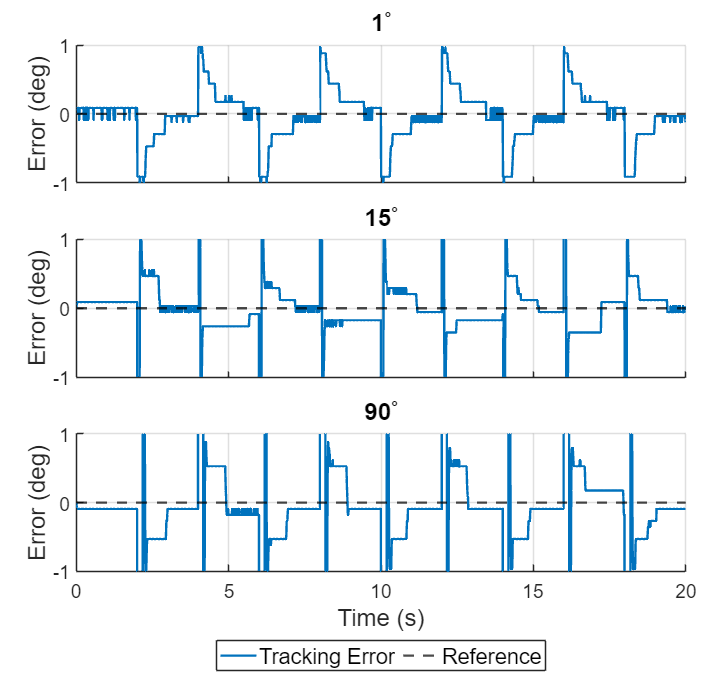



%% --- FIGURA 2: PLOT DELL'ERRORE (Error Plot) ---
f_err = figure('Name', 'Step Error', 'Color', 'w', 'Position', [300, 150, 800, 750]);
tl_err = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_leg_err = [];

for i = 1:3
    val = step_vals(i);
    fname = [file_step_base num2str(val) '.mat'];
    
    ax = nexttile;
    hold(ax, 'on'); grid(ax, 'on');
    set(ax, 'FontSize', font_size - 4);
    
    if exist(fname, 'file')
        d_step = load(fname);
        
        raw_meas = d_step.out.logsout.getElement(sig_norm).Values.Data(:) * K;
        raw_cmd  = d_step.out.logsout.getElement(sig_exp).Values.Data(:);
        time_vec = d_step.out.logsout.getElement(sig_norm).Values.Time(:);
        
        cmd_cut = raw_cmd(1:end-1);
        cmd_exp = repelem(cmd_cut, 10);
        
        len = min(length(cmd_exp), length(raw_meas));
        y_ref = cmd_exp(1:len) * K;
        y_meas = raw_meas(1:len);
        t_plot = time_vec(1:len);
        
        if i == 1 && length(y_meas) >= 592
             y_meas(592) = y_meas(591);
        end
        
        err_step_plot = y_meas - y_ref; 
        
        % Plot su asse specifico
        p_zero = yline(ax, 0, '--k', 'LineWidth', 2, 'DisplayName', 'Reference');
        p_err = plot(ax, t_plot, err_step_plot, '-', 'LineWidth', 2, 'DisplayName', 'Tracking Error');
        
        if i == 1
            h_leg_err = [p_err, p_zero];
        end
        
        % Formattazione
        ylabel(ax, 'Error (deg)', 'FontSize', font_size);
        title(ax, sprintf('%d^\\circ', val), 'FontSize', font_size);
        
        % --- LIMITI FISSI +-1 ---
        ylim(ax, [-1 1]);
        % ------------------------
        
    end
    
    if i < 3
        set(ax, 'XTickLabel', []);
    else
        xlabel(ax, 'Time (s)', 'FontSize', font_size);
    end
end

% Legenda condivisa in basso
if ~isempty(h_leg_err)
    lgd_err = legend(h_leg_err);
    lgd_err.Layout.Tile = 'South';
    lgd_err.Orientation = 'horizontal';
    lgd_err.FontSize = font_size - 2;
    lgd_err.Box = 'on';
end

% --- Salvataggio Crop Perfetto (Error) ---
if save_figures
    filename = fullfile(save_path, 'custom_step_error_multi.pdf');
    set(f_err, 'Units', 'centimeters'); 
    pos = get(f_err, 'Position');
    set(f_err, 'PaperUnits', 'centimeters');
    set(f_err, 'PaperSize', [pos(3) pos(4)]);
    set(f_err, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_err, filename, '-dpdf', '-painters');
end

%% ========================================================================
%% PARTE 4: CONFRONTO FINALE (ISTOGRAMMA COMPLETO)
%% ========================================================================
fprintf('--- 4. GENERAZIONE ISTOGRAMMA FINALE ---\n');

--- 4. GENERAZIONE ISTOGRAMMA FINALE ---


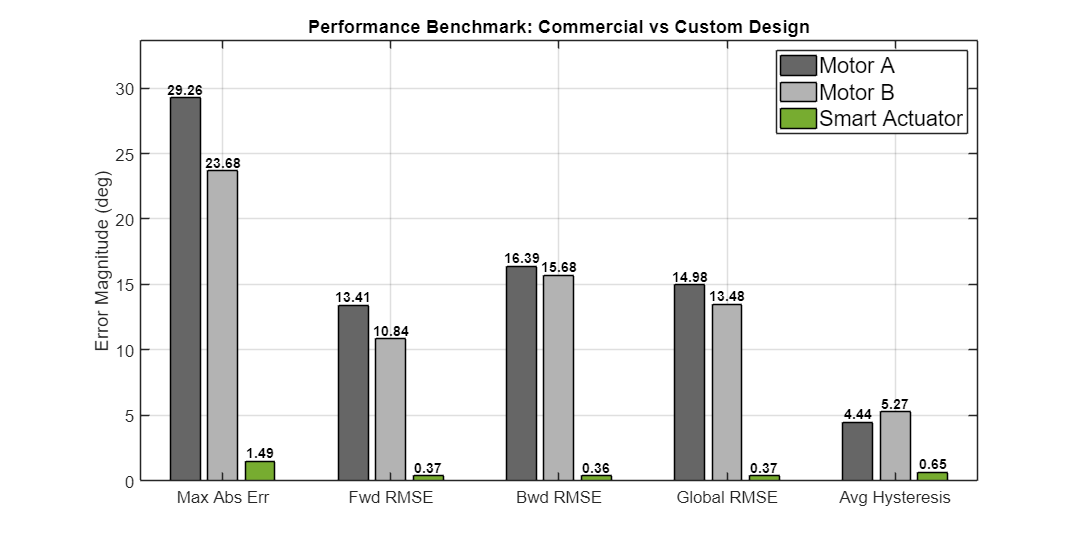

Grafico confronto finale salvato in: ../TESI/images/



% Struttura Matrice Dati: [Motore A, Motore B, Motore Custom]
metrics = [
    MaxErr_A,           MaxErr_B,           MaxErr_New;      % 1. Max Abs Error
    RMSE_FW_A,          RMSE_FW_B,          RMSE_FW_New;     % 2. RMSE Fwd
    RMSE_BW_A,          RMSE_BW_B,          RMSE_BW_New;     % 3. RMSE Bwd
    RMSE_Glob_A,        RMSE_Glob_B,        RMSE_Glob_New;   % 4. RMSE Glob
    Hyst_Avg_A,         Hyst_Avg_B,         Hyst_Avg_New;    % 5. Hysteresis
];

categories = {
    'Max Abs Err', ...
    'Fwd RMSE', ...
    'Bwd RMSE', ...
    'Global RMSE', ...
    'Avg Hysteresis'
    };

f_fin = figure('Name','Final Benchmark','Color','w','Position',[300,300,1200,600]);
b = bar(metrics, 'grouped');

b(1).FaceColor = col_motorA; 
b(2).FaceColor = col_motorB; 
b(3).FaceColor = col_new;    

grid on;
ylabel('Error Magnitude (deg)', 'FontSize', font_size);
title('Performance Benchmark: Commercial vs Custom Design', 'FontSize', font_size + 2);

xticks(1:length(categories));
xticklabels(categories);
ax = gca; ax.FontSize = font_size - 6;

legend({'Motor A', 'Motor B', 'Smart Actuator'}, ...
       'Location', 'northeast', 'FontSize', font_size - 2);

% Valori sopra le barre
for i = 1:3 
    x_pos = b(i).XEndPoints;
    y_pos = b(i).YEndPoints;
    for k = 1:length(y_pos)
        val = y_pos(k);
        if val > 0.001 % Nasconde gli zeri
            text(x_pos(k), val, sprintf('%.2f', val), ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', font_size - 8, ...
                'FontWeight', 'bold');
        end
    end
end

ylim([0, max(max(metrics)) * 1.15]);

if save_figures
    exportgraphics(f_fin, fullfile(save_path, 'final_benchmark.pdf'), 'ContentType', 'vector');
    fprintf('Grafico confronto finale salvato in: %s\n', save_path);
end


fprintf('\n=== ANALISI COMPLETATA CON SUCCESSO ===\n');


=== ANALISI COMPLETATA CON SUCCESSO ===
